## Example #1

### Random tetrahedron

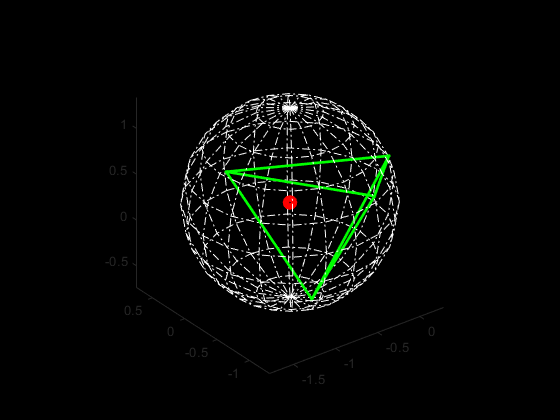

V = 2*(rand(3,4)-0.5);
[C, radius] = tetrahedron_circumscribed_sphere(V);
theta = (0:pi/10:pi)';
phi = (0:pi/10:2*pi);
xS = radius*sin(theta)*cos(phi);
yS = radius*sin(theta)*sin(phi);
zS = repmat(radius*cos(theta),1,length(phi));
figure;
set(gcf,'Color',[0 0 0]);
plot3(V(1,:),V(2,:),V(3,:),'g.','Linewidth',5), hold on;
plot3(C(1,1),C(2,1),C(3,1),'ro','Linewidth',5), hold on;
couples = combnk(1:4,2);
for k = 1:size(couples,1)
    line(V(1,couples(k,:)),V(2,couples(k,:)),V(3,couples(k,:)), 'Color', [0 1 0], 'Linewidth',2), hold on;
end
plot3(C(1,1)+xS(:,1:end),C(2,1)+yS(:,1:end),C(3,1)+zS(:,1:end),'w-.'), hold on;
plot3(C(1,1)+yS(1:end,:)',C(2,1)+xS(1:end,:)',C(3,1)+zS(1:end,:)','w-.'), hold on;
set(gca,'Color',[0 0 0]);
axis equal, axis tight;

## Example #2

### Flat tetrahedron

V1 = [2*sqrt(2)/3 0 -1/3];
V2 = [-sqrt(2)/3 sqrt(6)/3 -1/3];
V3 = [-sqrt(2)/3 -sqrt(6)/3 -1/3];
V4 = [0 0 -1/3];
V = [V1' V2' V3' V4'];
[C, radius] = tetrahedron_circumscribed_sphere(V);